# Introduction to autoregression

A timeseries is autocorrelated if the value at each timepoint depends on values at previous timepoints. This is relevant in many ecological contexts. 

If a timeseries is autocorrelated, it has structure which will confound certain analyses. An excellent example is that autocorrelated timeseries which are independent tend to appear correlated (see tutorial in introduction for demonstration).

In this introduction, we demonstrate how to identify when a timeseries is autocorrelated. Then, we demonstrate how to remove the autocorrelated component of a timeseries using autoregression.

## Simulating test data

First, we need to generate timeseries data. Autoregression (AR) models are a general framework for doing this. A simple, linear AR model is:


$$X_t =c+\sum_{k=1}^{p} \phi_k X_{t-k} +\varepsilon_t$$


where $X_t$ is the value at time $t$ and $X_{t-k}$ is the value at time $t-k$. (Here, $t$is an index, i.e. the $t^{\mathrm{th}}$ sampled timepoint.) The $\phi_k$ are the autoregression coefficients, and $p$ is the maximum time lag. Each $X_t$ then, is a linear combination of previous terms $X_{t-k}$. The $\varepsilon_t$ are noise, and $c$ is a constant.

Here, we generate several timeseries with different maximum time lags and autoregressive (AR) coefficients.

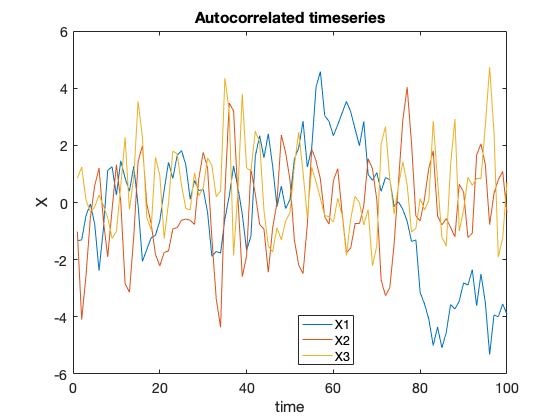

clear;

NT = 100; % number of timepoints
epsilon = normrnd(0,1,[NT 3]); % noise normally distributed ~N(0,1)

% specify AR coefficients
phi = [1 0 0; % first timeseries X1
    0.9 -0.5 0; % second timeseries X2
    0.8 -0.7 0.5]'; % third timeseries X3

p = sum(phi~=0); % maximum lags

X = zeros(NT,3);
for i = 1:3
    X(1:p(i),i) = cumsum(epsilon(1:p(i),i));
    for j = p(i)+1:NT
        X(j,i) = sum(X(j-1:-1:j-p(i),i).*phi(1:p(i),i)) + epsilon(j,i);
    end
end

figure();
plot(X);
xlabel('time');
ylabel('X');
legend({'X1','X2','X3'},'Location','best');
title('Autocorrelated timeseries');
set(gca,'FontSize',14);

## Partial autocorrelation to detect maximum time lag

Next, we compute the partial autocorrelation function for each timeseries. The partial autocorrelation indicates which lags are important.

threshold = 0.3; % arbitrary threshold for finding maximum lag

maxlags = 10; % how many lags to check
pac = zeros(maxlags+1,3);
p_hat = zeros(1,3); % estimated maximum lag
for i = 1:3
    [pac(:,i), lags] = parcorr(X(:,i),'NumLags',maxlags,'Method','Yule-Walker');
    p_hat(i) = find(abs(pac(:,i))>threshold,1,'last')-1;
end

% did partial autocorrelation correctly estimate the maximum lags?
fprintf('true maximum lag: %d %d %d\nestimated maximum lag: %d %d %d',p,p_hat);

true maximum lag: 1 2 3
estimated maximum lag: 1 2 3

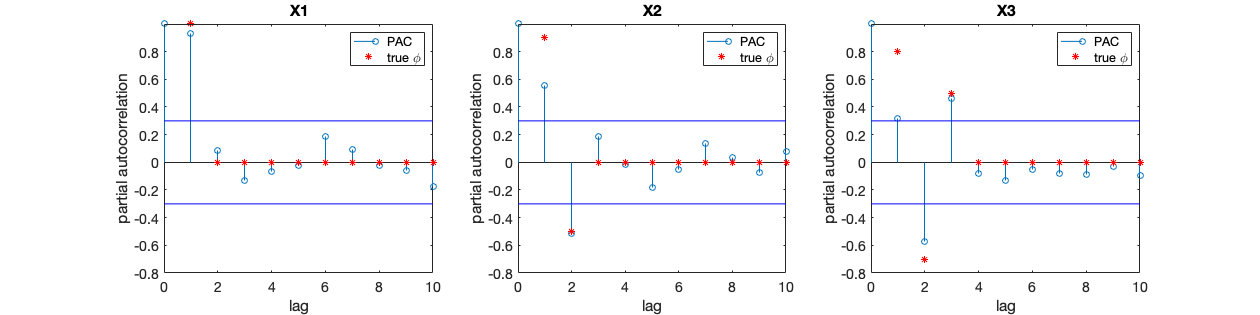

if ~all(p==p_hat)
    fprintf('WARNING: estimated maximum lags are not correct.\nAdjust threshold before computing AR coefficients.')
end

figure();
for i = 1:3
    subplot(1,3,i);
    stem(lags,pac(:,i));
    hold on;
    plot(1:p(i),phi(1:p(i),i),'r*'); % true phi
    plot(p(i)+1:maxlags,zeros(1,maxlags-p(i)),'r*');
    plot([0 maxlags],[threshold threshold],'b'); % threshold
    plot([0 maxlags],-[threshold threshold],'b');
    hold off;
    ylim([-0.8 1]);
    xlabel('lag');
    ylabel('partial autocorrelation');
    title(sprintf('X%d',i));
    legend({'PAC','true \phi'});
    set(gca,'FontSize',14);
end
resize_figure();

The results from partial autocorrelation can be used as a proxy for timescales of dynamical processes. For example, X1 is autocorrelated for the first time lag only. Therefore, we estimate that the turnover time of X1 is on the order of the sampling period.

## Estimating AR coefficients

Using the estimated maximum lags, we can now construct AR models to estimate the AR coefficients.

phi_hat = zeros(max(p_hat),3); % AR coefficients
for i = 1:3
    ar = arima(p_hat(i),0,0); % use the estimated maximum lag from pac
    ar_est = estimate(ar,X(:,i)); % estimate AR coefficients
    phi_hat(1:p_hat(i),i) = cell2mat(ar_est.AR)'; % collect estimated AR coefficients
end

 
    ARIMA(1,0,0) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue   
                ________    _____________    __________    ___________

    Constant    -0.26503       0.17018        -1.5574          0.11938
    AR{1}        0.94007      0.032395         29.019      3.8182e-185
    Variance       1.183       0.18951         6.2422       4.3147e-10

 
    ARIMA(2,0,0) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    -0.018253       0.10018        -0.1822  

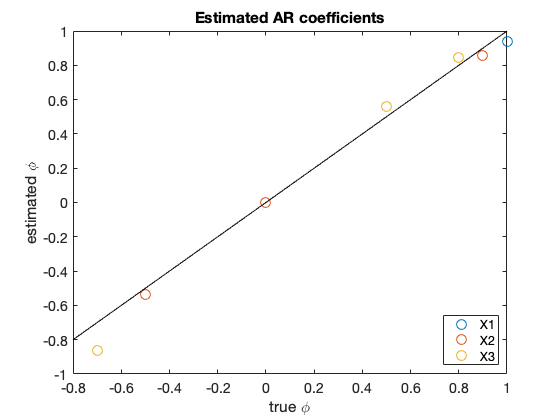

% pad with zeros if p and p_hat were different
if size(phi,1)~=size(phi_hat,1)
    tmpn = max(size(phi,1),size(phi_hat,1));
    phi = [phi; zeros(tmpn-size(phi,1),3)];
    phi_hat = [phi_hat; zeros(tmpn-size(phi_hat,1),3)];
end

figure();
plot(phi,phi_hat,'o','MarkerSize',10);
plot_one2one();
xlabel('true \phi');
ylabel('estimated \phi');
legend({'X1','X2','X3'},'Location','best');
title('Estimated AR coefficients');
set(gca,'FontSize',14);

The original AR coefficients are recovered fairly well, as long as the maximum lag $p$ is estimated correctly. 

## Computing residual timeseries

Once we have the AR coefficients, we can remove the autocorrelated component from the timeseries. This gives us the *residual* timeseries:


$$X_{t,\mathrm{residual}} =X_t -\sum_{k=1}^p \phi_k X_{t-k}$$


The residual timeseries is more appropriate for certain kinds of statistical analyses. For example, correlation and regression based analyses are often used to link variables together (e.g., bacteria A and bacteria B are associated). Performing these analyses on the original timeseries will lead to a high false positive rate.

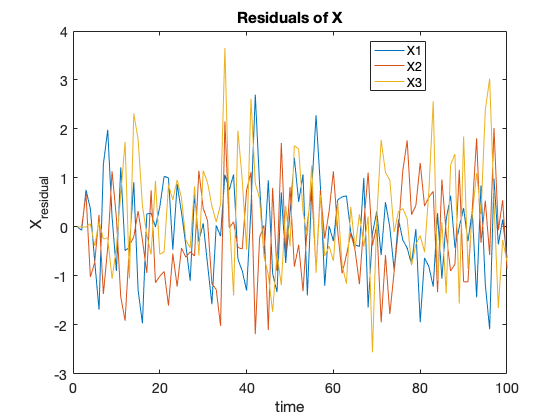

Xresidual = zeros(NT,3);
for i = 1:3
    for j = p_hat(i)+1:NT
        Xresidual(j,i) = X(j,i) - sum(X(j-1:-1:j-p_hat(i),i).*phi_hat(1:p_hat(i),i));
    end
end

figure();
plot(Xresidual);
legend({'X1','X2','X3'},'Location','best');
xlabel('time');
ylabel('X_{residual}');
title('Residuals of X')
set(gca,'FontSize',14);

In this tutorial, we used an AR model to generate the timeseries in the first place. Therefore, we can compare the estimated residuals to the true residuals to see how well our AR analysis performed.

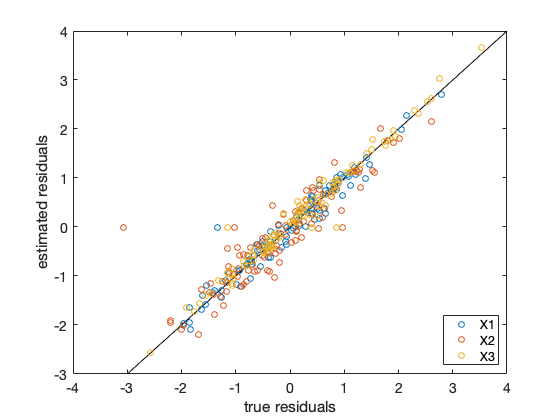

figure();
plot(epsilon,Xresidual,'o');
plot_one2one();
xlabel('true residuals');
ylabel('estimated residuals');
legend({'X1','X2','X3'},'Location','best');
set(gca,'FontSize',14);